## ***Numerical Differentiation***

*Estimating the Rate of Stress Increase in a Wooden Beam using Newton's Forward Formula*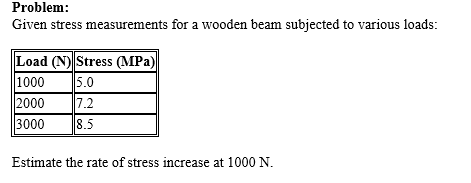

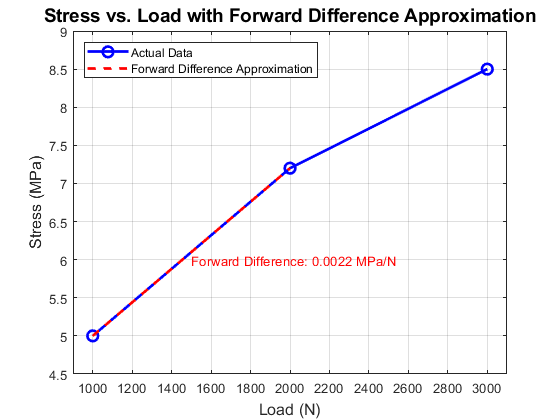

% Given Data
load_N = [1000, 2000, 3000]; % Load in Newtons
stress_MPa = [5.0, 7.2, 8.5]; % Stress in MPa

% Step Size
h = load_N(2) - load_N(1);

% Forward Difference Approximation
forward_difference = (stress_MPa(2) - stress_MPa(1)) / h;

% Create the plot
figure;
plot(load_N, stress_MPa, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
hold on;

x_fd = [load_N(1), load_N(1) + h];
y_fd = [stress_MPa(1), stress_MPa(1) + forward_difference * h];
plot(x_fd, y_fd, 'r--', 'LineWidth', 2);

xlabel('Load (N)', 'FontSize', 12);
ylabel('Stress (MPa)', 'FontSize', 12);
title('Stress vs. Load with Forward Difference Approximation', 'FontSize', 14);

legend('Actual Data', 'Forward Difference Approximation', 'Location', 'northwest');

text(1500, 6, sprintf('Forward Difference: %.4f MPa/N', forward_difference), ...
    'FontSize', 10, 'Color', 'r');
xlim([900, 3100]);
ylim([4.5, 9]);

grid on;

fprintf('Rate of Stress Increase at 1000 N: %.4f MPa/N\n', forward_difference);

Rate of Stress Increase at 1000 N: 0.0022 MPa/N


*Estimating the Rate of Moisture Loss at the End of a Drying Process using backward difference*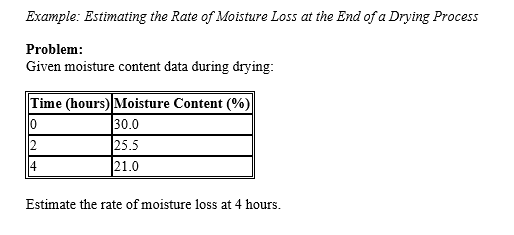


% Given data
time = [0, 2, 4];             % Time in hours
moisture_content = [30.0, 25.5, 21.0]; % Moisture content in %
clear length
% Calculate the backward difference
n = length(moisture_content);
delta_f = moisture_content(n) - moisture_content(n-1); % f(x_n) - f(x_(n-1))

% Calculate h (the time step)
h = time(n) - time(n-1); % Time difference (2 hours)

% Calculate the rate of moisture loss using backward difference
rate_moisture_loss = delta_f / h; % Moisture loss per hour (Backward difference)

% Display the result in the command window
fprintf('Rate of moisture loss: %.4f %% per hour\n', rate_moisture_loss);

Rate of moisture loss: -2.2500 % per hour


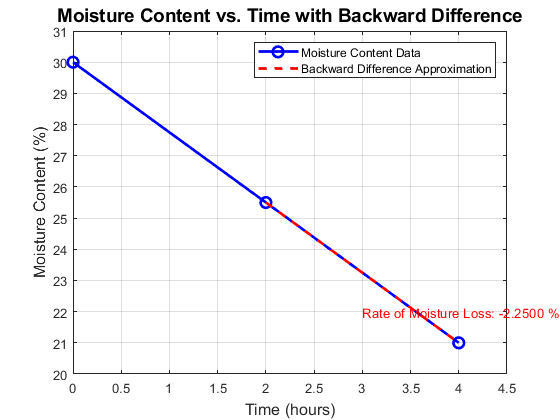


% Create the plot
figure;

% Plot moisture content vs time
plot(time, moisture_content, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
hold on;

% Highlight the backward difference calculation on the plot
x_fd = [time(n-1), time(n)];
y_fd = [moisture_content(n-1), moisture_content(n)]; % Line connecting two data points
plot(x_fd, y_fd, 'r--', 'LineWidth', 2);

% Add labels and title
xlabel('Time (hours)', 'FontSize', 12);
ylabel('Moisture Content (%)', 'FontSize', 12);
title('Moisture Content vs. Time with Backward Difference', 'FontSize', 14);

% Add legend
legend('Moisture Content Data', 'Backward Difference Approximation', 'Location', 'northeast');

% Add text annotation for the backward difference value
text(3, 22, sprintf('Rate of Moisture Loss: %.4f %%/hr', rate_moisture_loss), ...
    'FontSize', 10, 'Color', 'r');

% Adjust axis limits for better visibility
xlim([0, 4.5]);
ylim([20, 31]);

% Add grid
grid on;

*Calculating the Rate of Temperature Increase in a Bioenergy Reactor using forward difference*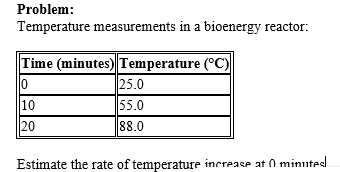

% Given data
time = [0, 10, 20];               % Time in minutes
temperature = [25.0, 55.0, 88.0]; % Temperature in °C

% Calculate the forward difference
delta_f = temperature(2) - temperature(1); % f(x_1) - f(x_0)

% Calculate h (the time step)
h = time(2) - time(1); % Time difference (10 minutes)

% Calculate the rate of temperature increase
rate_temp_increase = delta_f / h; % Rate of temperature increase (°C per minute)

% Display results
fprintf('Rate of Temperature Increase at 0 minutes: %.2f°C per minute\n', rate_temp_increase);

Rate of Temperature Increase at 0 minutes: 3.00°C per minute


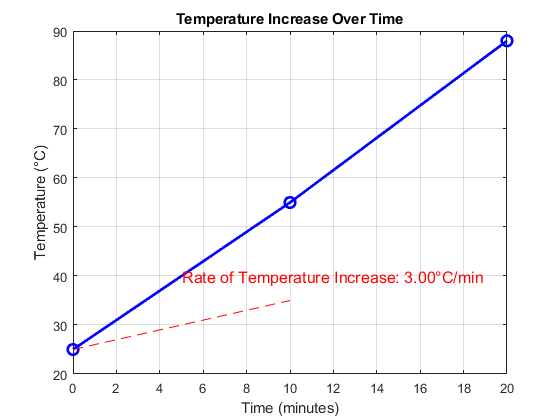


% Plotting the temperature increase over time
figure;

% Plot Temperature vs Time
plot(time, temperature, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('Time (minutes)');
ylabel('Temperature (°C)');
title('Temperature Increase Over Time');
grid on;

% Annotate rate of increase
text(5, 40, sprintf('Rate of Temperature Increase: %.2f°C/min', rate_temp_increase), 'FontSize', 12, 'Color', 'r');


hold on;
plot([0, 10], [25, 35], 'r--');  % A line for the calculated rate over the interval
hold off;

*Estimating the Rate of Heat Transfer in a Wood Sample*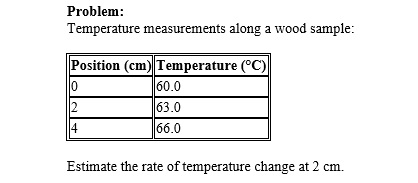

% Estimating the Rate of Stress Increase in a Wooden Beam

% Given Data
load_N = [1000, 2000, 3000]; % Load in Newtons
stress_MPa = [5.0, 7.2, 8.5]; % Stress in MPa

% Step Size
h = load_N(2) - load_N(1);

% Forward Difference Approximation
forward_difference = (stress_MPa(2) - stress_MPa(1)) / h;

% Create the plot
figure;
plot(load_N, stress_MPa, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
hold on;

% Plot the forward difference approximation
x_fd = [load_N(1), load_N(1) + h];
y_fd = [stress_MPa(1), stress_MPa(1) + forward_difference * h];
plot(x_fd, y_fd, 'r--', 'LineWidth', 2);


xlabel('Load (N)', 'FontSize', 12);
ylabel('Stress (MPa)', 'FontSize', 12);
title('Stress vs. Load with Forward Difference Approximation', 'FontSize', 14);
legend('Actual Data', 'Forward Difference Approximation', 'Location', 'northwest');
text(1500, 6, sprintf('Forward Difference: %.4f MPa/N', forward_difference), ...
    'FontSize', 10, 'Color', 'r');


xlim([900, 3100]);
ylim([4.5, 9]);

% Add grid
grid on;



fprintf('Rate of Stress Increase at 1000 N: %.4f MPa/N\n', forward_difference);

Rate of Stress Increase at 1000 N: 0.0022 MPa/N


*Calculating the Rate of Shrinkage in a Wood Panel*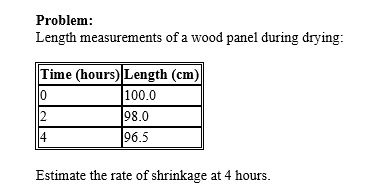

% Given data
time = [0, 2, 4];                % Time in hours
length = [100.0, 98.0, 96.5];    % Length in cm

% Calculate the backward difference
n = length(3);       % Length at 4 hours
n_minus_1 = length(2);  % Length at 2 hours
delta_length = n - n_minus_1; % f(x_n) - f(x_(n-1))

% Calculate h (the time step)
h = time(3) - time(2); % Time difference (2 hours)

% Calculate the rate of shrinkage
rate_shrinkage = delta_length / h; % Rate of shrinkage (cm per hour)

% Display results
fprintf('Rate of Shrinkage at 4 hours: %.2f cm per hour\n', rate_shrinkage);

Rate of Shrinkage at 4 hours: -0.75 cm per hour


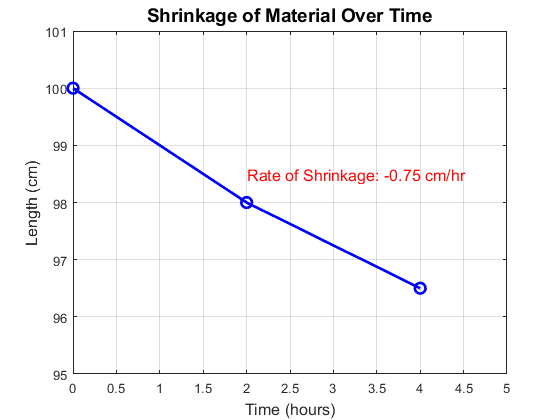


% Visualization: Plot Length vs Time
figure;
plot(time, length, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('Time (hours)', 'FontSize', 12);
ylabel('Length (cm)', 'FontSize', 12);
title('Shrinkage of Material Over Time', 'FontSize', 14);
grid on;

text(2, 98.5, sprintf('Rate of Shrinkage: %.2f cm/hr', rate_shrinkage), 'FontSize', 12, 'Color', 'r');

% Display the plot
xlim([0, 5]);
ylim([95, 101]);

## Numerical Integration

**Calculating the Total Stress on a Wooden Beam**

**Problem:**Given a beam with a varying stress distributionf(x) = 2x + 1 over the interval [0,10], estimate the total stress using the Trapezoidal Rule with n=4 intervals.

% Define the function to be integrated
f = @(x) 2 * x + 1;  % Function representing the total stress on a wooden beam

% Define the interval [a, b] and number of intervals n
a = 0;   % Lower bound
b = 10;  % Upper bound
n = 4;   % Number of intervals

% Calculate step size
h = (b - a) / n;

% Initialize the result
trapezoidal_result = f(a) + f(b);

% Compute the intermediate terms
for i = 1:n-1
    x_i = a + i * h;
    trapezoidal_result = trapezoidal_result + 2 * f(x_i);
end

% Finalize the trapezoidal rule calculation
trapezoidal_result = (h / 2) * trapezoidal_result;

% Display the result
fprintf('total stress: %.4f\n', trapezoidal_result);

total stress: 110.0000


**Estimating the Energy Output in a Bioenergy Reactor**

**Problem:**Given the energy output function $f(x) = x^2$ over the interval [1,5], estimate the total energy using Simpson’s One-Third Rule with n = 4 intervals.

% Simpson's One-Third Rule Integration

% Define the function to integrate
f = @(x) x.^2;  % The function is f(x) = x^2

% Define the integration limits and number of intervals
a = 1;    % Lower limit of integration
b = 5;    % Upper limit of integration
n = 4;    % Number of sub-intervals (must be even for Simpson's rule)

% Calculate the step size (h)
h = (b - a) / n;    % Step size

% Evaluate the function at equally spaced points
x = linspace(a, b, n+1);  % Create array of points from a to b
fx = f(x);    % Evaluate the function at those points

% Apply Simpson's One-Third Rule formula
I_simp = (h/3) * (fx(1) + 4*sum(fx(2:2:end-1)) + 2*sum(fx(3:2:end-2)) + fx(end));

% Display the result of integration
disp(['Energy Output: ', num2str(I_simp)]);

Energy Output: 41.3333


**Calculating the Volume of a Wooden Cylinder**

**Problem:**Given the volume function $f(x) = \pi x^2$ over the interval [2,5], estimate the total volume using Simpson’s Three-Eighth Rule with n=3 intervals.

% Simpson's Three-Eighth Rule Integration

% Define the function to integrate
f = @(x) pi*x.^2;  % The function is f(x) = pi*x^2

% Define the integration limits and number of intervals
a = 2;    % Lower limit of integration
b = 5;    % Upper limit of integration
n = 3;    % Number of sub-intervals (must be a multiple of 3)

% Calculate the step size (h)
h = (b - a) / n;    % Step size

% Evaluate the function at equally spaced points
x = linspace(a, b, n+1);  % Create array of points from a to b
fx = f(x);    % Evaluate the function at those points

% Apply Simpson's Three-Eighth Rule formula
I_simp38 = (3*h/8) * (fx(1) + 3*sum(fx(2:3:end-1)) + 3*sum(fx(3:3:end-2)) + 2*sum(fx(4:3:end-3)) + fx(end));

% Display the result of integration
disp(['Volume of Wooden Cylinder: ', num2str(I_simp38)]);

Volume of Wooden Cylinder: 65.9734


**Estimating the Wood Volume in a Log**

Problem: Given the volume function f(x)= xover the interval [1,4], estimate the total volume using Boole’s Rule with n=4 intervals.


% Boole's Rule Integration

% Define the function to integrate
f = @(x) x;  % The volume function f(x) = x

% Define the integration limits and number of intervals
a = 1;    % Lower limit of integration
b = 4;    % Upper limit of integration
n = 4;    % Number of sub-intervals (must be a multiple of 4 for Boole's Rule)

% Step size calculation
h = (b - a) / n;    % Step size

% Evaluate the function at specified points
x = a:h:b;  % Create an array of points from a to b
fx = f(x);  % Evaluate the function at those points

% Applying Boole's Rule
I_boole = (7 * h / 90) * (7 * fx(1) + 32 * (fx(2) + fx(4)) + 12 * fx(3) + 7 * fx(5));

% Display the result of integration
disp(['Estimated Volume using Boole''s Rule: ', num2str(I_boole)]);

Estimated Volume using Boole's Rule: 13.125


**Calculating the Heat Transfer in a Biomaterial**

**Problem:** Given the heat transfer function $f(x) = x^3$ over the interval [0,3], estimate the total heat transfer using Weddle’s Rule with n=6 intervals

% Weddle's Rule Integration

% Define the heat transfer function to integrate
f = @(x) x.^3;  % The heat transfer function f(x) = x^3

% Define the integration limits and number of intervals
a = 0;    % Lower limit of integration
b = 3;    % Upper limit of integration
n = 6;    % Number of sub-intervals (must be a multiple of 6 for Weddle's Rule)

% Step size calculation
h = (b - a) / n;    % Step size

% Evaluate the function at specified points
x = a:h:b;  % Create an array of points from a to b
fx = f(x);  % Evaluate the function at those points

% Applying Weddle's Rule
I_weddle = (3 * h / 10) * (fx(1) + 5 * (fx(2) + fx(4) + fx(6)) + 2 * (fx(3) + fx(5)) + 5 * fx(7));

% Display the result of integration
disp(['Estimated Heat Transfer using Weddle''s Rule: ', num2str(I_weddle)]);

Estimated Heat Transfer using Weddle's Rule: 37.2937


## **Errors in Numerical Methods**

**Trapezoidal Rule Error**

Estimate the error in the Trapezoidal Rule for the function$f\left(x\right)=x^2 $  over [1,4]with n=4 intervals, applied to estimate the stress distribution in a wooden beam

% Trapezoidal Rule Error Estimation

% Define the function
f = @(x) x.^2;  % The function f(x) = x^2

% Define the integration limits and number of intervals
a = 1;    % Lower limit of integration
b = 4;    % Upper limit of integration
n = 4;    % Number of sub-intervals

% Compute exact integral
exact_integral = (b^3 / 3) - (a^3 / 3);  % Exact value of the integral

% Step size calculation
h = (b - a) / n;    % Step size

% Evaluate the function at specified points
x = a:h:b;  % Create an array of points from a to b
fx = f(x);  % Evaluate the function at those points

% Applying the Trapezoidal Rule
I_T = (h / 2) * (fx(1) + 2 * sum(fx(2:end-1)) + fx(end));

% Compute error estimate
f_double_prime = 2;  % Second derivative of f(x) = x^2
error_estimate = -((b - a) / (12 * n^2)) * f_double_prime;

% Display results
disp(['Exact Integral: ', num2str(exact_integral)]);

Exact Integral: 21


disp(['Estimated Integral using Trapezoidal Rule: ', num2str(I_T)]);

Estimated Integral using Trapezoidal Rule: 21.2812


disp(['Error Estimate: ', num2str(error_estimate)]);

Error Estimate: -0.03125


**Simpson’s One-Third Rule Error**

Estimate the error in Simpson’s One-Third Rule for the function $f\left(x\right)=e^{x\;}$ over [0,2] with n=4 intervals, applied to estimate the energy output of a bioenergy system.

% Simpson's One-Third Rule Error Estimation

% Define the function
f = @(x) exp(x);  % The function f(x) = e^x

% Define the integration limits and number of intervals
a = 0;    % Lower limit of integration
b = 2;    % Upper limit of integration
n = 4;    % Number of sub-intervals

% Compute exact integral
exact_integral = exp(b) - exp(a);  % Exact value of the integral

% Step size calculation
h = (b - a) / n;    % Step size

% Evaluate the function at specified points
x = a:h:b;  % Create an array of points from a to b
fx = f(x);  % Evaluate the function at those points

% Applying Simpson's One-Third Rule
I_S = (h / 3) * (fx(1) + 4 * sum(fx(2:2:end)) + 2 * sum(fx(3:2:end)) + fx(end));

% Compute error estimate
f_fourth_derivative = exp(x);  % Fourth derivative of f(x) = e^x
error_estimate = -((b - a)^5 / (180 * n^4)) * max(f_fourth_derivative);

% Display results
disp(['Exact Integral: ', num2str(exact_integral)]);

Exact Integral: 6.3891


disp(['Estimated Integral using Simpson’s One-Third Rule: ', num2str(I_S)]);

Estimated Integral using Simpson’s One-Third Rule: 8.8542


disp(['Error Estimate: ', num2str(error_estimate)]);

Error Estimate: -0.0051313
